## Image loading

img = imread('Important_files/film1_big.jpg');

img_crop_height = 1:(size(img,1)/5)-2;
img_crop_width = (size(img,2)/3)+2:(2*size(img,2)/3)-5;

img_rgb = img(img_crop_height,img_crop_width,:);
img_rc = img(img_crop_height,img_crop_width,1);
img_gc = img(img_crop_height,img_crop_width,2);
img_bc = img(img_crop_height,img_crop_width,3);

imwrite(img_rgb, 'img_rgb.jpg');
imwrite(img_rc, 'img_rc.jpg');
imwrite(img_gc, 'img_gc.jpg');
imwrite(img_bc, 'img_bc.jpg');
% Om du ser detta så är detta funktioner som verkar finnas för att göra
% liknande det vi vill :)
% imshow(locallapfilt(img_rgb,0.1,4),[]);
% imshow(locallapfilt(img_rgb,0.1,10),[]);

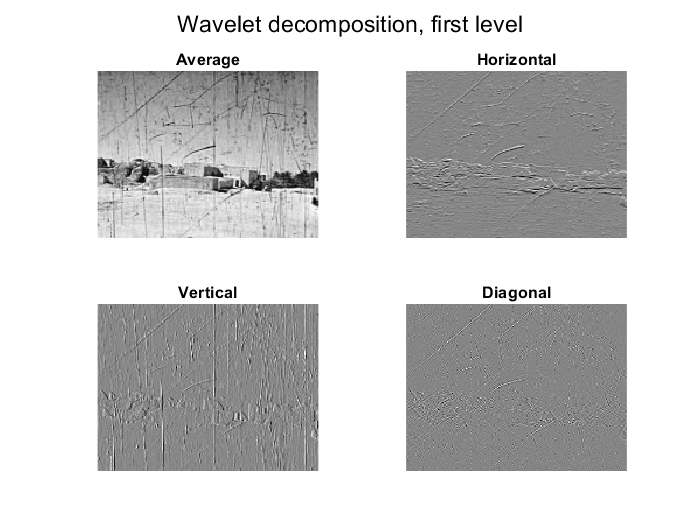

[cA, cH, cV, cD] = dwt2(double(img_rc), 'haar');
showgrid({cA, cH, cV, cD},["Average";"Horizontal";"Vertical";"Diagonal"],2,2);
sgtitle('Wavelet decomposition, first level') 

clf();  

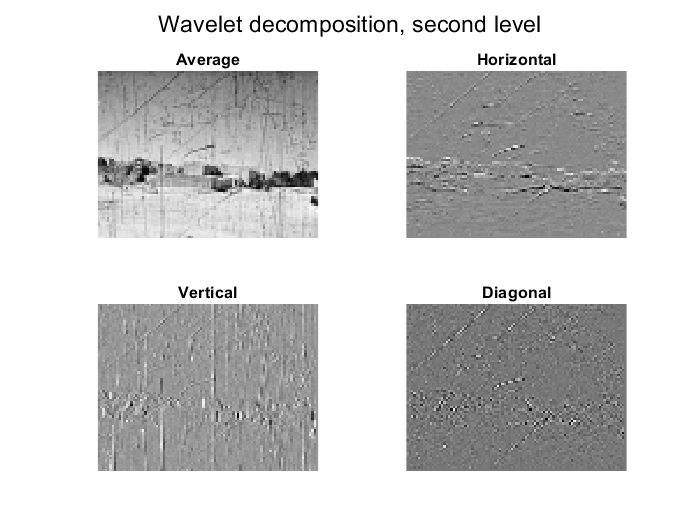

[cA2, cH2, cV2, cD2] = dwt2(double(cA), 'haar');
showgrid({cA2, cH2, cV2, cD2},["Average";"Horizontal";"Vertical";"Diagonal"],2,2);
sgtitle('Wavelet decomposition, second level') 

clf();  

## Masks

%DETAILS
details_mask = detailsmask(img_rgb);
imwrite(details_mask, 'detail_mask.jpg');

% Masks for Color channels
rgb_color_mask = rgbmask(img_rgb); %RGB
imwrite(rgb_color_mask, 'rgb_mask.jpg');

% HSV
color_mask = hsvnarrow(img_rgb);
imwrite(color_mask, 'color_mask.jpg');

scratch_mask = details_mask & color_mask;
imwrite(scratch_mask, 'scratch_mask.jpg');

dilated_scratch_mask = imdilate(details_mask & color_mask, true(3));
imwrite(dilated_scratch_mask, 'dilated_scratch_mask.jpg');

%filters
H_sz=9;
H_center = uint8(H_sz/2);
padding = double(H_center-1);

H_gauss = fspecial('gaussian',H_sz,2);

H_lap = zeros(H_sz);
H_lap(H_center-1:H_center+1,H_center-1:H_center+1) = fspecial('laplacian',0.5);

Results = {};

BWs = {scratch_mask,details_mask,color_mask,dilated_scratch_mask};
BW_names = ["";"_w_only_wav_mask";"_w_only_thres_mask";"_w_dilated_mask"];

for bwi = 1:numel(BWs)
    BW = BWs{bwi};
    [sz_rows, sz_cols] = size(BW);
    [row_idx,col_idx] = find(BW==1);
    
    lap_rest = img_rgb;
    gauss_rest = img_rgb;
    mean_rest = img_rgb;
    
    for i = 1:numel(row_idx)
        r = row_idx(i);
        c = col_idx(i);
        r_min = max(1, r - padding);
        r_max = min(sz_rows, r + padding);
        c_min = max(1, c - padding);
        c_max = min(sz_cols, c + padding);
        rows = r_min:r_max;
        cols = c_min:c_max;
        
        BW_neighbors = BW(rows, cols, :);
        RGB_neighbors = img_rgb(rows, cols, :);
        O_neighbors = double(RGB_neighbors).*repmat(~BW_neighbors, [1,1,3]);
        
        if ~isequal(size(BW_neighbors),[H_sz H_sz])
            H_lap_cropped = H_lap(H_center-(r-r_min):H_center+(r_max-r),H_center-(c-c_min):H_center+(c_max-c));
            LAP_neighbors = double(RGB_neighbors).*repmat(H_lap_cropped, [1,1,3]);
            
            H_gauss_cropped = H_gauss(H_center-(r-r_min):H_center+(r_max-r),H_center-(c-c_min):H_center+(c_max-c));
            H_gauss_cropped = H_gauss_cropped.*~BW_neighbors;
            H_gauss_cropped = H_gauss_cropped./sum(H_gauss_cropped,[1 2]);
            GAUSS_neighbors = double(RGB_neighbors).*repmat(H_gauss_cropped, [1,1,3]);
        else
            LAP_neighbors = double(RGB_neighbors).*repmat(H_lap, [1,1,3]);
            H_gauss_masked = H_gauss.*~BW_neighbors;
            H_gauss_masked = H_gauss_masked./sum(H_gauss_masked,[1 2]);
            GAUSS_neighbors = double(RGB_neighbors).*repmat(H_gauss_masked, [1,1,3]);
        end
         
        gauss_rest(r,c,:) = sum(GAUSS_neighbors,[1 2]);
        lap_rest(r,c,:) = sum(LAP_neighbors,[1 2]);
        mean_rest(r,c,:) = sum(O_neighbors,[1 2])./(nnz(O_neighbors)/3);
    end
    Results{bwi} = {img_rgb,BW,gauss_rest};
    
    imwrite(mean_rest, strcat('restored_with_mean',BW_names(bwi),'.jpg'));
    imwrite(gauss_rest, strcat('restored_with_gauss',BW_names(bwi),'.jpg'));
end

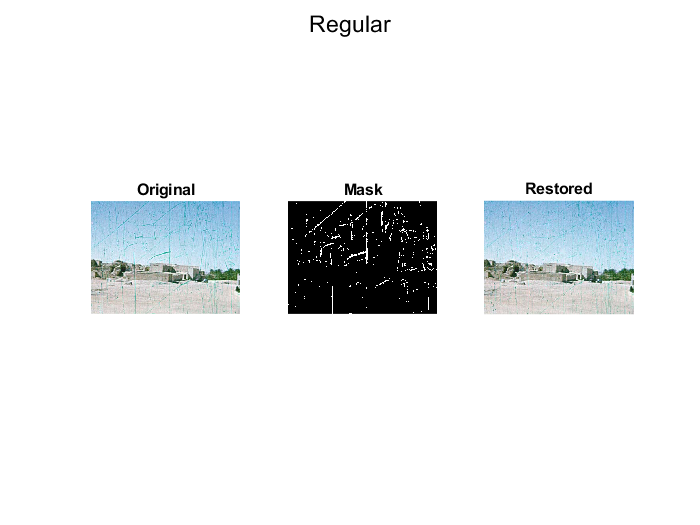

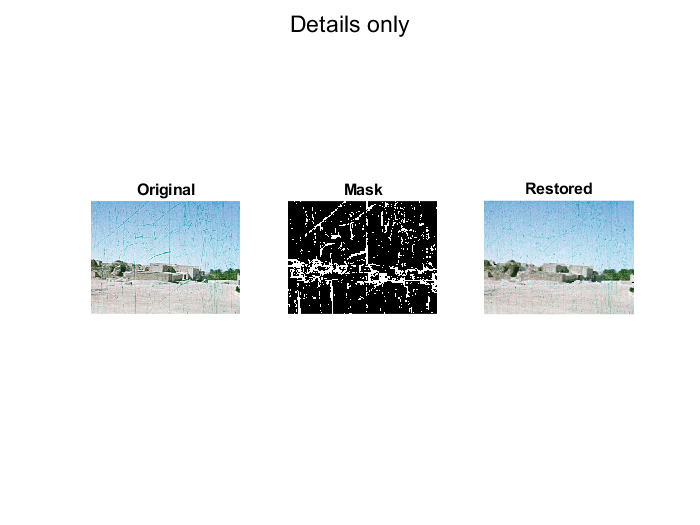

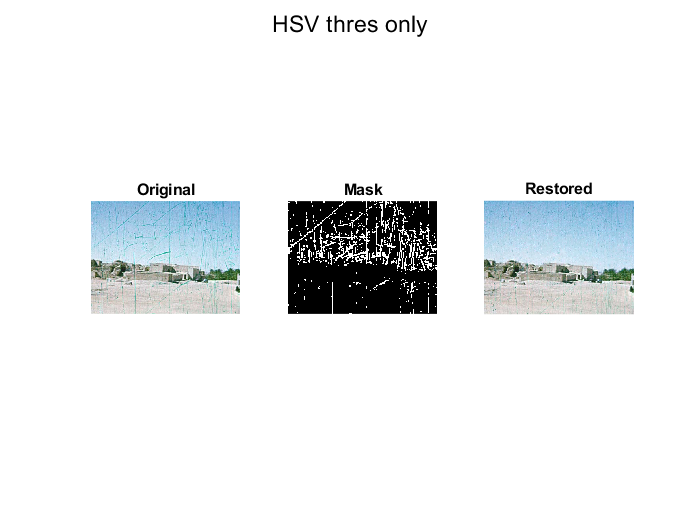

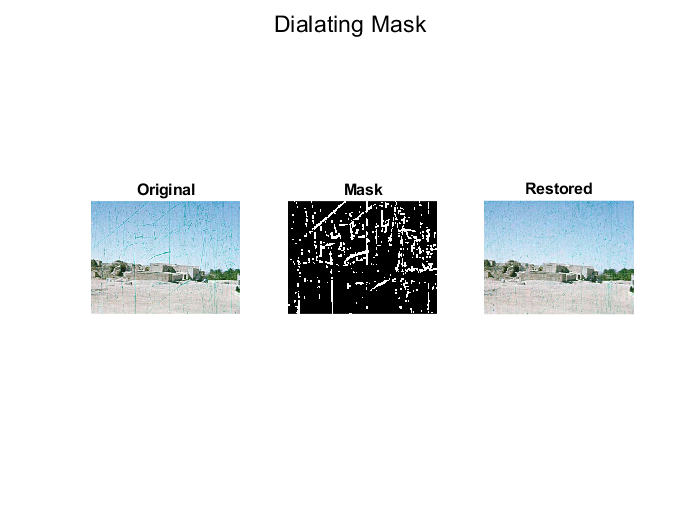

sgt = ["Regular","Details only","HSV thres only","Dialating Mask","Dialating Thres","Dialating details"];
for i = 1:numel(Results)
    showgrid(Results{i}, ["Original";"Mask";"Restored"]);
    sgtitle(sgt(i)) 
    %clf();  
end

## **Functions**

function cls = d2bw(c,threshold) % details transformed to binary image with estimated threshold
    if nargin < 2
        threshold = (1-graythresh(abs(c)))*max(max(abs(c)));
    end
    cls = abs(c) >= threshold;
end

%RGB thresholds
function mask = rgbmask(I)
    red = I(:,:,1) >= 0 & I(:,:,1) <= 162;
    green = I(:,:,2) >= 134 & I(:,:,2) <= 228;
    blue = I(:,:,3) >= 149 & I(:,:,3) <= 211;
    mask = red & green & blue;
end

function mask = hsvnarrow(I)
I = rgb2hsv(I);
% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.420;
channel1Max = 0.550;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.124;
channel2Max = 1.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.579;
channel3Max = 1.000;

% Create mask based on chosen histogram thresholds
mask = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);

end

%HSV threshold
function mask = hsvmask(I)
    I = rgb2hsv(I);
    %old values
%         hue = I(:,:,1) >= 0.336 & (I(:,:,1) <= 0.563);
%         saturation = I(:,:,2) >= 0.138;
%         value = I(:,:,3) >= 0.632 & I(:,:,3) <= 0.883;
    hue = I(:,:,1) >= 0.3 & (I(:,:,1) <= 0.574);
    saturation = I(:,:,2) >= 0.055;
    value = I(:,:,3) >= 0.528 & I(:,:,3) <= 0.899;
    mask = hue & saturation & value;

% Define thresholds for channel 1 based on histogram settings
% channel1Min = 0.403;
% channel1Max = 0.563;
% 
% % Define thresholds for channel 2 based on histogram settings
% channel2Min = 0.112;
% channel2Max = 1.000;
% 
% % Define thresholds for channel 3 based on histogram settings
% channel3Min = 0.543;
% channel3Max = 1.000;
% 
% % Create mask based on chosen histogram thresholds
% mask = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
%     (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
%     (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
end

function mask = auramask(I)
I = rgb2hsv(I);
% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.394;
channel1Max = 0.550;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.086;
channel2Max = 1.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.835;
channel3Max = 1.000;

% Create mask based on chosen histogram thresholds
mask = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
end

function F = showgrid(ims, ts, r, c)
    if nargin < 3
        r = 1;
        c = numel(ims);
    end
    F = figure;
    for i = 1:numel(ims)
        subplot(r,c,i);
        imshow(ims{i}, []);
        title(ts(i));
    end
end

function details_mask = detailsmask(I)
    I_size = size(I(:,:,1));
    details_mask = zeros(I_size);
    for color = 1:3
        [cA, cH, cV, cD] = dwt2(double(I(:,:,color)), 'haar');
        [cA2, cH2, cV2, cD2] = dwt2(double(cA), 'haar');
    
        cV_full = imresize(d2bw(cV), I_size, 'nearest');
        cH_full = imresize(d2bw(cH), I_size, 'nearest');
        cD_full = imresize(d2bw(cD), I_size, 'nearest');
        full1 = cV_full | cH_full | cD_full;
        imwrite(full1, 'detail_mask_1.jpg');
    
        cV2_full = imresize(d2bw(cV2), I_size, 'nearest');
        cH2_full = imresize(d2bw(cH2), I_size, 'nearest');
        cD2_full = imresize(d2bw(cD2), I_size, 'nearest');
        full2 = cV2_full | cH2_full | cD2_full;
        imwrite(full2, 'detail_mask_2.jpg');
    
        details_mask = details_mask | full1 | full2;
    end
end